# Introduction to Drones - 22AIE448

**3D Mapping using a Monocular Camera and Control by Visual-Inertial Odometry (VIO)**

Group CD2 : Ravishanmugam K, Ishwarya Murugesan, Aparna Bharani, Cibikumar B, Akhilan S

School of Artificial Intelligence, Amrita Vishwa Vidyapeetham

**Toy model 3 - Model 1, Part 3 : geometric SO(3) control and the closed loop (blocks 5 to 8)**

Run this file with the folder `toy_model3` as the current folder (it uses `DroneLib.m`).

clearvars
clear all
ready = true;
PUBLISH = not(ready);   % make this PUBLISH = ready; to export the file as PDF

clearvars -except PUBLISH ready

## Block 5 - Position control (outer loop)

Compare where we are (from the EKF) with where we should be:


$$e_p = p_d - \hat{p}, \qquad e_v = v_d - \hat{v} \qquad \rightarrow (15)$$



$$a_d = \ddot{p}_d + K_p\,e_p + K_v\,e_v \qquad \rightarrow (16)$$


**Why it works.** If the drone really gets the acceleration $a_d$, then $\ddot{e}_p = \ddot{p}_d - a_d$, so


$$\ddot{e}_p + K_v\,\dot{e}_p + K_p\,e_p = 0$$


which is a mass-spring-damper on every axis: $s^2 + k_v s + k_p = 0$. Both roots have negative real part whenever $k_p, k_v > 0$, so the error dies out. Matching $s^2 + 2\zeta\omega_n s + \omega_n^2$:


$$\omega_n = \sqrt{k_p}, \qquad \zeta = \frac{k_v}{2\sqrt{k_p}}, \qquad t_{settle} \approx \frac{4}{\zeta\,\omega_n}$$


P  = DroneLib.params();
kp = diag(P.Kp);  kv = diag(P.Kv);
wn = sqrt(kp);  zeta = kv./(2*sqrt(kp));  t_settle = 4./(zeta.*wn);
table(["x";"y";"z"], kp, kv, wn, zeta, t_settle, VariableNames=["axis","kp","kv","wn","zeta","t_settle"])

ans = 3×6 table
    axis    kp     kv       wn       zeta      t_settle
    ____    ___    ___    ______    _______    ________

    "x"     1.5    1.2    1.2247     0.4899     6.6667 
    "y"     1.5    1.2    1.2247     0.4899     6.6667 
    "z"       2    1.5    1.4142    0.53033     5.3333 


**Toy example.** Setpoint $p_d = [0,0,2]$ m (`controller.yaml`), $v_d = \ddot{p}_d = 0$. EKF says $\hat{p} = [0.1,\,-0.2,\,1.5]$ m and $\hat{v} = [0,\,0,\,0.3]$ m/s.


$$e_p = [-0.1,\ 0.2,\ 0.5], \qquad e_v = [0,\ 0,\ -0.3]$$



$$a_d = [1.5(-0.1),\ 1.5(0.2),\ 2(0.5) + 1.5(-0.3)] = [-0.15,\ 0.30,\ 0.55]\textrm{ m/s}^2$$


It is 50 cm low, so it wants to go up; it is already climbing, so it asks for less (0.55 instead of 1.0).

p_hat = [0.1; -0.2; 1.5];   v_hat = [0; 0; 0.3];
p_d   = [0; 0; 2];          v_d = [0; 0; 0];     a_ff = [0; 0; 0];
e_p = p_d - p_hat

e_p =    -0.1000
    0.2000
    0.5000


e_v = v_d - v_hat

e_v =          0
         0
   -0.3000


a_d = a_ff + P.Kp*e_p + P.Kv*e_v

a_d =    -0.1500
    0.3000
    0.5500


## Block 6 - Force and attitude (which way to lean)

From (2) we need $T R e_3 = m(a_d - g)$. A quadrotor can only push along its own $z$ axis, so that axis must point along the desired force:


$$F_d = m\,(a_d - g) \qquad \rightarrow (17)$$



$$b_{3d} = \frac{F_d}{||F_d||} \qquad \rightarrow (18)$$



$$b_{1c} = [\cos\psi_d,\ \sin\psi_d,\ 0]^T, \quad b_{2d} = \frac{b_{3d} \times b_{1c}}{||b_{3d} \times b_{1c}||}, \quad b_{1d} = b_{2d} \times b_{3d}, \quad R_d = [\,b_{1d}\ \ b_{2d}\ \ b_{3d}\,] \qquad \rightarrow (19)$$


The three columns are unit length and at right angles, so $R_d^T R_d = I$ and $\det R_d = 1$. No roll / pitch / yaw angles are used, so there is no gimbal lock.

F_d = P.m*(a_d - P.g)                 % N (more than the 14.7 N weight: it also climbs)

F_d =    -0.2250
    0.4500
   15.5400


b3d = F_d/norm(F_d);
psi_d = 0;
b1c = [cos(psi_d); sin(psi_d); 0];
b2d = cross(b3d, b1c)/norm(cross(b3d, b1c));
b1d = cross(b2d, b3d);
R_d = [b1d b2d b3d]

R_d =     0.9999         0   -0.0145
    0.0004    0.9996    0.0289
    0.0145   -0.0289    0.9995


tilt_deg = acosd(b3d(3))

tilt_deg = 1.8543

check_orthonormal = norm(R_d'*R_d - eye(3))

check_orthonormal = 1.1113e-16

## Block 7 - Attitude control on SO(3) (inner loop)


$$e_R = \frac{1}{2}\left(R_d^T\hat{R} - \hat{R}^T R_d\right)^{\vee} \qquad \rightarrow (20)$$



$$e_\omega = \hat{\omega} - \hat{R}^T R_d\,\omega_d \qquad \rightarrow (21)$$



$$\tau = -K_R e_R - K_\omega e_\omega + \hat{\omega} \times J\hat{\omega} - J\left([\hat{\omega}]_\times \hat{R}^T R_d\,\omega_d - \hat{R}^T R_d\,\dot{\omega}_d\right) \qquad \rightarrow (22)$$



$$T = F_d \cdot \hat{R}\,e_3 \qquad \rightarrow (23)$$


**Where (20) comes from.** The "distance" between two attitudes is $\Psi = \frac{1}{2}\textrm{trace}(I - R_d^T\hat{R}) = 1 - \cos\varphi$ ($\varphi$ = angle between them). Its slope when the drone turns a little is exactly $e_R$, so $e_R$ points "uphill" and the torque $-K_R e_R$ pushes downhill. For one axis, $e_R = \sin\varphi\,n \approx \varphi\,n$.

**Why it is stable.** Put (22) into (4): every nonlinear term cancels and $J\dot{e}_\omega = -K_R e_R - K_\omega e_\omega$. The energy $V = \frac{1}{2}e_\omega^T J e_\omega + k_R\Psi$ then changes as


$$\dot{V} = -k_\omega\,||e_\omega||^2 \le 0$$


so it can only go down: the drone returns to $R_d$ from every attitude except exactly upside down.

**Toy example: recovering from a 10 degree roll** that is still rolling at 0.2 rad/s, with $R_d = I$:


$$e_R = [\sin 10^\circ,\ 0,\ 0] = [0.1736,\ 0,\ 0], \qquad e_\omega = [0.2,\ 0,\ 0]$$



$$\tau_x = -4(0.1736) - 0.8(0.2) = -0.8546\textrm{ N m}, \qquad T = 14.715\cos 10^\circ = 14.491\textrm{ N}$$


R_hat = DroneLib.expSO3([deg2rad(10); 0; 0]);
w_hat = [0.2; 0; 0];
Rd = eye(3);  w_d = zeros(3,1);  wdot_d = zeros(3,1);
Fd = [0; 0; P.m*P.g0];
e_R = 0.5*DroneLib.vee(Rd'*R_hat - R_hat'*Rd)

e_R =     0.1736
         0
         0


e_w = w_hat - R_hat'*Rd*w_d

e_w =     0.2000
         0
         0


tau = -P.KR*e_R - P.Kw*e_w + cross(w_hat, P.J*w_hat) ...
      - P.J*(DroneLib.hat(w_hat)*R_hat'*Rd*w_d - R_hat'*Rd*wdot_d)

tau =    -0.8546
         0
         0


T = dot(Fd, R_hat*P.e3)

T = 14.4914

**Recovery from 60 degrees** (rotation only, $k_R = 4$, $k_\omega = 0.8$), and the energy $V$ that never increases:

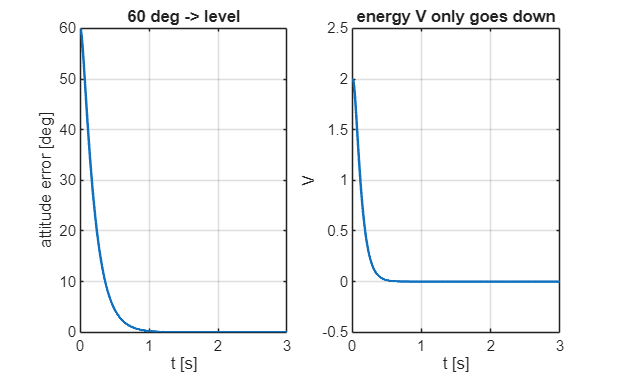

kR = 4;  kw = 0.8;
dt = 0.002;  n = 1500;  tt = (0:n)*dt;
x = DroneLib.pack([0;0;2], zeros(3,1), DroneLib.expSO3(deg2rad(60)*[1;1;0]/sqrt(2)), zeros(3,1));
ang = zeros(1,n+1);  V = zeros(1,n+1);
for k = 1:n+1
    [~, ~, R, w] = DroneLib.unpack(x);
    eR = 0.5*DroneLib.vee(R - R');                  % equation (20) with R_d = I
    ang(k) = rad2deg(norm(DroneLib.logSO3(R)));
    V(k)   = 0.5*w'*P.J*w + kR*0.5*trace(eye(3) - R);
    tq = -kR*eR - kw*w + cross(w, P.J*w);
    x = DroneLib.rk4(x, [P.m*P.g0; tq], dt, P);
end
figure
subplot(1,2,1); plot(tt, ang, LineWidth=1.5); grid on
xlabel("t [s]"); ylabel("attitude error [deg]"); title("60 deg -> level")
subplot(1,2,2); plot(tt, V, LineWidth=1.5); grid on
xlabel("t [s]"); ylabel("V"); title("energy V only goes down")

final_error_deg = ang(end)

final_error_deg = 1.9801e-06

## Block 8 - Control allocation (four motor speeds)

Rotor $i$ at $(x_i, y_i)$ pushes $f_i$. Summing forces and moments:


$$\left[\begin{array}{c} T\\ \tau \end{array}\right] = \Gamma f, \qquad \Gamma = \left[\begin{array}{cccc} 1 & 1 & 1 & 1\\ y_1 & y_2 & y_3 & y_4\\ -x_1 & -x_2 & -x_3 & -x_4\\ \kappa_1 c_m & \kappa_2 c_m & \kappa_3 c_m & \kappa_4 c_m \end{array}\right] \qquad \rightarrow (24)$$



$$f_i = k_f\,\Omega_i^2 \quad \Rightarrow \quad \Omega_i = \sqrt{\frac{(\Gamma^{-1}u)_i}{k_f}}\ \ \textrm{clipped to } [\Omega_{min},\ \Omega_{max}] \qquad \rightarrow (25)$$


Gamma = P.Gamma

Gamma =     1.0000    1.0000    1.0000    1.0000
   -0.2200    0.2200    0.2200   -0.2200
   -0.1300    0.1300   -0.1300    0.1300
   -0.0160   -0.0160    0.0160    0.0160


[Omega, f] = DroneLib.mixer([P.m*P.g0; 0; 0; 0], P);
f_hover     = f'          % N per rotor

f_hover =     3.6787    3.6788    3.6787    3.6788


Omega_hover = Omega'      % rad/s

Omega_hover =   655.9990  655.9990  655.9990  655.9990


[Omega, f] = DroneLib.mixer([T; tau], P);
f_roll     = f'

f_roll =     4.5940    2.6517    2.6517    4.5940


Omega_roll = Omega'       % right-side rotors 1 and 4 speed up -> it rolls back

Omega_roll =   733.0743  556.9522  556.9522  733.0743


## The closed loop: truth -> sensors -> EKF -> blocks 5-7 -> mixer -> truth

Everything of Model 1 together. The controller only sees the EKF estimate.

clearvars -except PUBLISH ready
P = DroneLib.params();
rng(7);
dt = 0.01;  t = 0:dt:25;  N = numel(t);
x  = DroneLib.pack([0.3;-0.3;1.8], zeros(3,1), eye(3), zeros(3,1));      % truth
xh = DroneLib.boxplus(x, [0.2;-0.1;0.1; 0.1;0;0; 0.03;-0.03;0.05; 0;0;0]); % EKF guess
Pk = blkdiag(0.3^2*eye(3), 0.2^2*eye(3), 0.1^2*eye(3), 0.05^2*eye(3));
Hg = [zeros(3,9) eye(3)];  Hc = [eye(3) zeros(3,9); zeros(3,6) eye(3) zeros(3,3)];
Rg = 0.01^2*eye(3);  Rc = blkdiag(0.05^2*eye(3), 0.02^2*eye(3));
Q  = blkdiag(1e-8*eye(3), (0.2/P.m*dt)^2*eye(3), 1e-8*eye(3), (5e-4/P.J(1,1)*dt)^2*eye(3));
Xt = zeros(18,N);  Xe = zeros(18,N);  Ref = zeros(3,N);  Om = zeros(4,N);
for k = 1:N
    [p, ~, R, w] = DroneLib.unpack(x);
    [~, ~, ~, wh] = DroneLib.unpack(xh);                          % sensors -> EKF
    [xh, Pk] = DroneLib.ekf_update(xh, Pk, w + 0.01*randn(3,1) - wh, Hg, Rg);
    if mod(k-1, 4) == 0
        [ph, ~, Rh] = DroneLib.unpack(xh);
        Rm = R*DroneLib.expSO3(0.02*randn(3,1));
        r  = [p + 0.05*randn(3,1) - ph; DroneLib.logSO3(Rh'*Rm)];
        [xh, Pk] = DroneLib.ekf_update(xh, Pk, r, Hc, Rc);
    end
    ref = DroneLib.helix(t(k));                                   % blocks 5-7 on the ESTIMATE
    [ph, vh, Rh, wh] = DroneLib.unpack(xh);
    u = DroneLib.so3_control(ph, vh, Rh, wh, ref, P);
    [Om(:,k), ~, u_app] = DroneLib.mixer(u, P);                   % block 8
    Xt(:,k) = x;  Xe(:,k) = xh;  Ref(:,k) = ref.p;
    gust = [0.2*randn(3,1); 5e-4*randn(3,1)];
    x  = DroneLib.rk4(x, u_app, dt, P, gust);                     % block 1 (the real drone)
    [xh, Pk] = DroneLib.ekf_predict(xh, Pk, u_app, dt, P, Q);
end
s = t > 5;
tracking_rmse_cm   = 100*sqrt(mean(sum((Xt(1:3,s) - Ref(:,s)).^2, 1)))

tracking_rmse_cm = 4.6806

estimation_rmse_cm = 100*sqrt(mean(sum((Xt(1:3,s) - Xe(1:3,s)).^2, 1)))

estimation_rmse_cm = 2.1840

motor_speed_range  = [min(Om(:,s), [], 'all') max(Om(:,s), [], 'all')]

motor_speed_range =   648.5441  664.3427


figure
plot3(Ref(1,:), Ref(2,:), Ref(3,:), 'k:', LineWidth=1.2); hold on
plot3(Xt(1,:), Xt(2,:), Xt(3,:), 'b', LineWidth=1.5)
plot3(Xe(1,:), Xe(2,:), Xe(3,:), 'r--'); hold off
grid on; axis equal; view(35, 25)
xlabel("x [m]"); ylabel("y [m]"); zlabel("z [m]")
legend("desired helix", "true flight", "EKF estimate")
title("Model 1 closed loop in wind")

## What our ROS 2 node actually sends

`controller_node.py` computes all of blocks 5-7 with `SO3Controller.compute()` and publishes $e_p, e_v, F_d, R_d, e_R, e_\omega, \tau$ for monitoring. ArduPilot's `/ap/v1/cmd_vel` topic accepts **velocities**, not force and torque, so `publish_velocity_command()` sends


$$v_{cmd} = 0.8\,e_p + 0.2\,e_v, \qquad \textrm{scaled down so that } ||v_{cmd}|| \le \textrm{max\_velocity} = 1\textrm{ m/s}$$


and ArduPilot runs its own blocks 5-8 to reach that velocity. For the toy state of block 5:

e_p = [-0.1; 0.2; 0.5];  e_v = [0; 0; -0.3];
v_cmd = 0.8*e_p + 0.2*e_v;
if norm(v_cmd) > 1.0, v_cmd = v_cmd*1.0/norm(v_cmd); end
v_cmd

v_cmd =    -0.0800
    0.1600
    0.3400


if(PUBLISH == ready)
    mlxfile = matlab.desktop.editor.getActive().Filename;
    [folder, name, ext] = fileparts(mlxfile);
    outfilepdf = fullfile(folder, 'pdf', [name, ext, '.pdf']);
    export(mlxfile, outfilepdf);
    if ispc
        winopen(outfilepdf);
    elseif ismac
        system(['open ' char(outfilepdf)]);
    else
        system("env -u LD_LIBRARY_PATH xdg-open '" + outfilepdf + "' &");
    end
end